# 基础题

## Problem 1

要求输出十行数据，第 n 行的数据是从 1 开始到 n 结束的连续自然整数。

arr = zeros(1, 10);
for i = 1 : 10
    arr(i) = i;
    disp(arr(1: i));
end

     1

     1     2

     1     2     3

     1     2     3     4

     1     2     3     4     5

     1     2     3     4     5     6

     1     2     3     4     5     6     7

     1     2     3     4     5     6     7     8

     1     2     3     4     5     6     7     8     9

     1     2     3     4     5     6     7     8     9    10



## Problem 2

假设有两个球筐，每个球筐里各有九个球，标号都是 1 到 9，每次分别从各个 筐里取一个球，用程序模拟随机取球过程，模拟 10000 次，那么取到同一数字的概率是多少？（利用 for 循环）

pool = randi(9, 10000, 2);
same = 0;
for i = 1 : length(pool(:, 1))
    if pool(i, 1) == pool(i, 2)
        same = same + 1;
    end
end
disp("取到同一数字的概率是 " + same / 100 + " %");

取到同一数字的概率是 11.07 %


## Problem 3

一只青蛙从井底往外跳，假设井有 20 米深，每次青蛙能跳 3 米，但会滑落 1.5 米，问多少次后青蛙能跳出井口？（利用 while 循环）

high = 0;
k = 0;
while true
    high = high + 3;
    k = k + 1;
    if high >= 20
        break;
    end
    high = high - 1.5;
end
disp(k + " 次后青蛙能跳出井口");

13 次后青蛙能跳出井口


## Problem 4

模拟某班 50 名同学的期末考试成绩，分别是语数外，分数分布在[40 100]分， 要求利用 for 循环筛选出每科成绩最高分和总分的最高分。

grades = randi(61, 50, 3) + 39;

kokugo = 0;
suugaku = 0;
eigo = 0;
total = 0;

for i = 1 : length(grades(:, 1))
    kokugo = max(grades(i, 1), kokugo);
    suugaku = max(grades(i, 2), suugaku);
    eigo = max(grades(i, 3), eigo);
    total = max(total, sum(grades(i, :)));
end

disp("语文最高分: " + kokugo);

语文最高分: 98


disp("数学最高分: " + suugaku);

数学最高分: 100


disp("外语最高分: " + eigo);

外语最高分: 100


disp("总分最高分: " + total);

总分最高分: 281


## Problem 5

生成一个分布在[-10 50]的 10×20 的矩阵，要求利用关系运算和逻辑运算，输 出大于等于 10，小于等于 30 的数。

mat = rand(10, 20) * 60 - 10;
for i = 1 : 10
    for j = 1 : 20
        if mat(i, j) >= 10 && mat(i, j) <= 30
            disp(mat(i, j));
        end
    end
end

   27.0302

   24.0407

   12.0525

   22.1137

   21.8769

   21.1519

   14.0055

   15.0801

   20.2115

   27.1625

   10.7305

   19.1279

   10.9490

   26.7800

   29.0807

   18.6974

   16.6534

   22.9620

   12.9798

   13.9102

   21.8827

   22.9761

   12.4770

   10.6901

   16.6827

   14.0845

   21.2366

   12.2361

   20.3310

   15.2886

   17.2758

   10.2485

   26.7576

   14.4148

   17.1739

   26.4450

   16.8899

   17.4705

   21.3881

   17.0782

   13.0488

   18.1288

   17.1047

   11.8069

   25.4158

   29.4331

   26.5632

   26.0677

   25.6126

   28.9780

   18.3727

   19.2704

   25.3660

   16.2727

   13.5069

   27.8795

   24.8516

   16.8856

   23.8846

   28.3711

   21.5070

   29.1902

   11.8670

   10.7535

   23.4058

   27.8859

   16.5652

   12.6609

   15.9365

   22.3667



## Problem 6

价值千万的航天服上边为什么会有字印反？主要是考虑镜像。现试着用矩阵 来描述一个对勾图案，并实现镜像的效果。

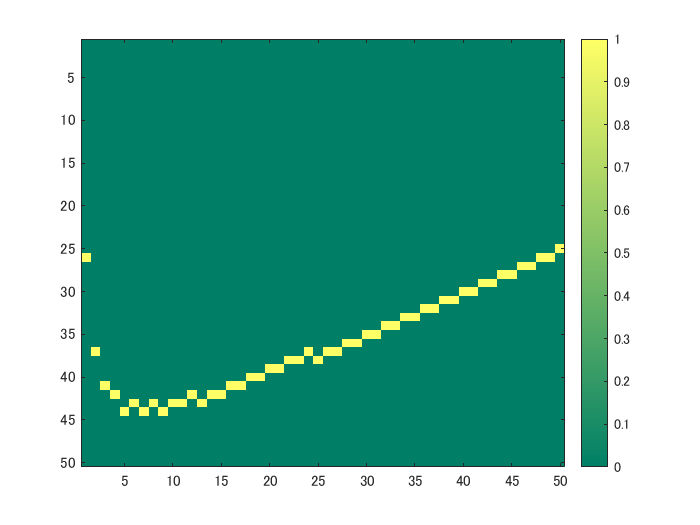

f = @(x) [floor(x), fix(x / 2) + fix(24 / x)];
mat = zeros(50, 50);
for i = 1 : 50
    pt = f(i);
    mat(50 - pt(2), pt(1)) = 1;
end
figure;
imagesc(mat);
colormap summer;
colorbar;

## Problem 7